%% READ nwb file created for Neurolabware system and the SpecSeg toolbox

[fn, pn] = uigetfile('*.nwb');
nwb = nwbRead(fullfile(pn, fn), 'ignorecache');

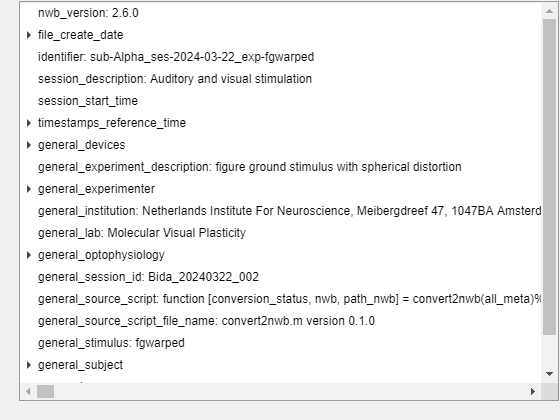

util.nwbTree(nwb)

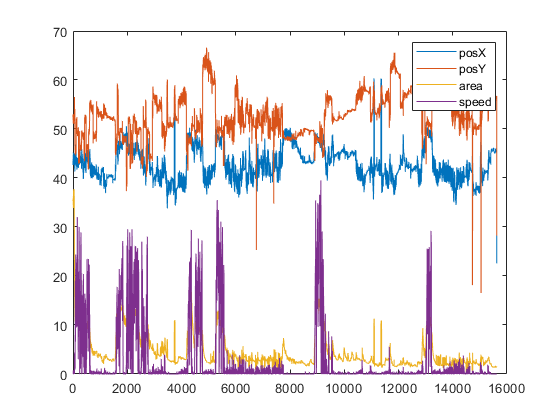

pupil_area = nwb.processing.get('behavior').nwbdatainterface.get('BehavioralTimeSeries') ...
    .timeseries.get('Pupil_area').data.load;
pupil_pos = nwb.processing.get('behavior').nwbdatainterface.get('BehavioralTimeSeries') ...
    .timeseries.get('Pupil_position').data.load;
run_speed = nwb.processing.get('behavior').nwbdatainterface.get('BehavioralTimeSeries') ...
    .timeseries.get('Run_speed').data.load;

figure, plot([pupil_pos', pupil_area/100, run_speed])
legend({'posX', 'posY', 'area', 'speed'})

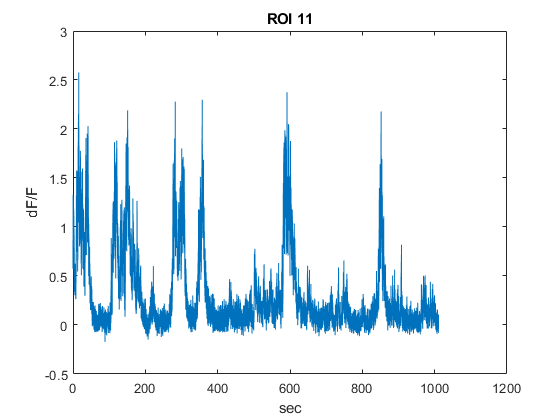

roidata = nwb.processing.get('ophys').nwbdatainterface.get('Fluorescence') ...
    .roiresponseseries.get('RoiResponseSeries').data.load;

frametimes = nwb.processing.get('ophys').nwbdatainterface.get('Fluorescence') ...
    .roiresponseseries.get('RoiResponseSeries').timestamps.load;

roi = 11;
plot(frametimes , roidata(:,roi))
xlabel('sec')
ylabel('dF/F')
title(['ROI ' num2str(roi)])

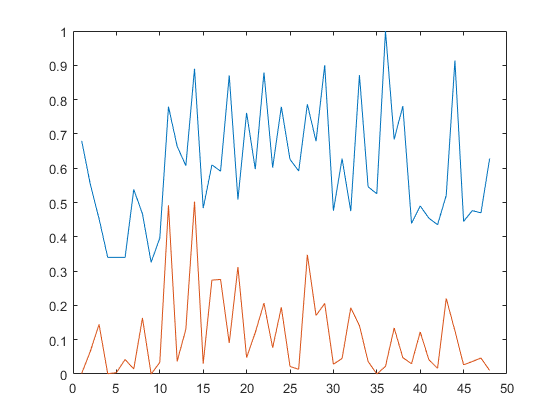


roiarea = nwb.processing.get('ophys').nwbdatainterface.get('ImageSegmentation') ...
    .planesegmentation.get('PlaneSegmentation').vectordata.get('roi_area').data.load;

roicov= nwb.processing.get('ophys').nwbdatainterface.get('ImageSegmentation') ...
    .planesegmentation.get('PlaneSegmentation').vectordata.get('roi_covariance').data.load;

roidelay= nwb.processing.get('ophys').nwbdatainterface.get('ImageSegmentation') ...
    .planesegmentation.get('PlaneSegmentation').vectordata.get('roi_delay').data.load;

figure, plot([roiarea/max(roiarea), roicov])

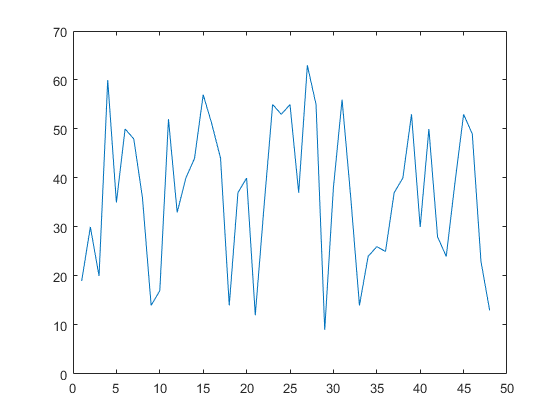

figure, plot(roidelay)

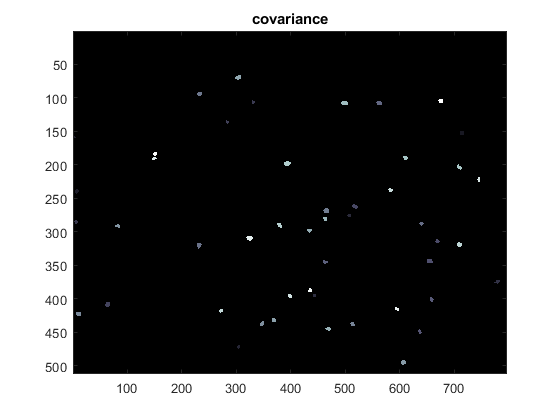



mask = nwb.processing.get('ophys').nwbdatainterface.get('ImageSegmentation') ...
    .planesegmentation.get('PlaneSegmentation').pixel_mask.data.load;
indx = nwb.processing.get('ophys').nwbdatainterface.get('ImageSegmentation') ...
    .planesegmentation.get('PlaneSegmentation').pixel_mask_index.data.load;



lb = 0;
im = ones(796, 512) * -5;
for i = 1:length(indx)
    ln = lb + double(indx(i));
    for j = lb+1:ln
        im(mask.x(j), mask.y(j)) = i;
    end
    lb = ln;
end

figure, imagesc(im')
title('covariance')
colormap bone


data = nwb.acquisition.get('2pInternal').data(:,:,1:500);

Error using containers.Map/subsref
The specified key is not present in this container.

Error in types.untyped.Set/get (line 170)
                o{i} = obj.Map(name{i});


imagesc(data(:,:,50))
cl = caxis;
cl(2) = cl(2) * 0.6;

for i = 1:500
    imagesc(data(:,:,i))
    caxis(cl)
    colormap('gray')
    drawnow()
    pause(0.03)
end
